Opgaver

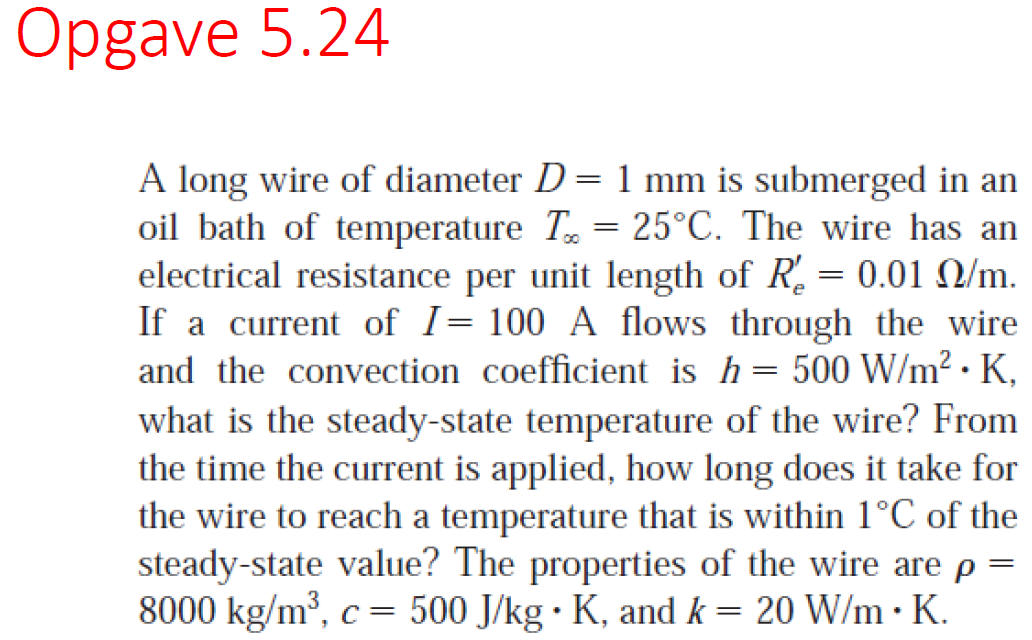

clear all
clf
T_inf = 25 + 273.15; % K
D = 1e-3; %m
I = 100; %A
R_e = 0.01; %ohm/m
h = 500; % W/(m^2 * K)
rho = 8000; % kg/m^3
c_p = 500; %J/(kg * K)
k = 20; % W/(m * K)
r = D/2;
syms L T_t

A = 2 * pi * r * L

$$A = \frac{\pi \,L}{1000}$$

V = L * pi * r^2

$$V = \frac{4722366482869645\,\pi \,L}{18889465931478580854784}$$

P = R_e * I^2

P = 100


tau_0 = rho * V *c_p / (h * A) % sekunder

$$tau\_0 = \frac{73786976294838203125}{36893488147419103232}$$

vpa(tau_0, 10)

$$ans = 2.0$$

q_eq = P == h * A/L * (T_t - T_inf)

$$q\_eq = 100=\frac{\pi \,\left(T_{t}-\frac{5963}{20}\right)}{2}$$


T_t = solve(q_eq, T_t)

$$T\_t = \frac{2\,\left(\frac{5963\,\pi }{40}+100\right)}{\pi }$$

vpa(T_t, 10) - 273.15

$$ans = 88.66197723675813424648595173494$$

**Opgave 5.37**

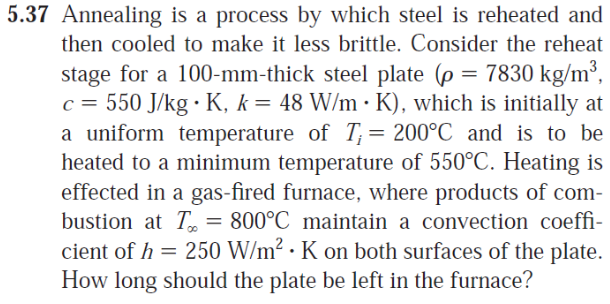

clear all
L = 0.1 

L = 0.1000

Lc = L/2

Lc = 0.0500


c = 550

c = 550

rho = 7830

rho = 7830

Ti = 200 + 274

Ti = 474

T_0 = 550 + 274

T_0 = 824

Tinf = 800 + 274

Tinf = 1074

h = 250

h = 250

k = 48

k = 48


Bi = (h*Lc)/k 

Bi = 0.2604


syms zeta_n

alpha = k/(rho*c)

alpha = 1.1146e-05


%Opslags værdig 

zeta = 0.5 

zeta = 0.5000

C1 = 1.042

C1 = 1.0420


syms t

Fo = vpa((alpha * t)/Lc^2, 5) 

$$Fo = 0.0044584\,t$$


theta = (T_0 - Tinf)/(Ti - Tinf)

theta = 0.4167


t = solve(theta == C1 * exp(-zeta^2 * Fo))

$$t = 822.37164507722027002213606808002$$


vpa(t)

$$ans = 822.37164507722027002213606808002$$

**Opgave 5.67**

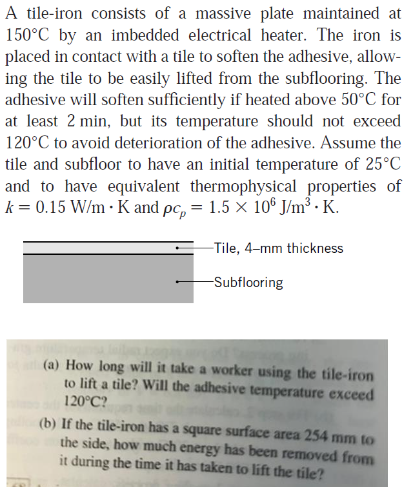

clear all
Ts = 150 + 274

Ts = 424

Ti = 25 + 274

Ti = 299

T = 50 + 274

T = 324

L = 0.004

L = 0.0040


Theta_star = (T-Ts) / (Ti - Ts)

Theta_star = 0.8000


% vi putter den ind i tabel 2b for at få 0.92 


%hvor Theta_star svare til erf(w) og w er den værdig vi gerne ville have

Theta_star_erf = 0.92 

Theta_star_erf = 0.9200


k = 0.15

k = 0.1500

pc = 1.5E6 

pc = 1500000

alpha = k/pc

alpha = 1.0000e-07


syms t0

t = vpa(solve(Theta_star_erf == (L/ (2*sqrt(alpha * t0)))), 5)

$$t = 47.259$$


%så tager det 2 min for at det bliver blødt efter varmen er opnået.

t_tot = t + 120

$$t\_tot = 167.25897920604620594531297683716$$


%temperatur efter den temperatur er opnået: 

syms T_final

% Nu går vi så den anden vej, hvor vi udregne højre side og så sætter det
% lige W for at finde erf W og så sætter man den lig theta for at finde
% T_final. 

L/ (2*sqrt(alpha * t_tot))

$$ans = 0.48902974389695092373814233970159$$


T_final_final = solve( (T_final-Ts) / (Ti - Ts) == 0.50275, T_final)

$$T\_final\_final = \frac{11557}{32}$$


T_final_C = vpa(T_final_final - 274, 5)

$$T\_final\_C = 87.156$$